# **H.264 Video Compression:**

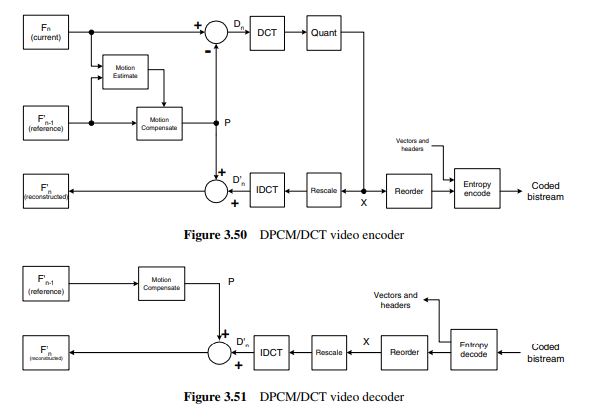

- **The Block consists of both an encoder, which is used to compress video data, and a decoder, which is used to decompress the data. The hybrid DPCM/DCT codec model is based on the idea of using motion estimation and compensation to reduce redundancy in the video data, followed by a transform stage and entropy encoding to further compress the data.**

- **The encoding process begins by dividing the video frame into blocks (called macroblocks) and comparing each block to a reference frame. A motion estimation function is used to find a region in the reference frame that is similar to the current block, and the offset between the two regions is stored as a motion vector. A motion compensated prediction is then generated based on the motion vector, and the difference between the prediction and the current block is calculated. This difference, called the residual or difference block, is then transformed using the discrete cosine transform (DCT) and quantized. The quantized transform coefficients are then reordered and run-level coded, and the coefficients, motion vector, and associated header information are entropy encoded to produce the compressed bitstream.**

- **The decoding process is the reverse of the encoding process. The compressed bitstream is entropy decoded to extract the coefficients, motion vector, and header information for each block. The coefficients are rescaled and inverse transformed to produce a decoded residual, and the motion vector is used to locate a region in the reference frame that becomes the motion compensated prediction. The prediction is added to the residual to produce a reconstructed block, and the reconstructed blocks are saved to produce the decoded frame.**

- **The hybrid DPCM/DCT codec model has been the basis for several major video coding standards, including H.261, H.263, MPEG-1, MPEG-2, MPEG-4 Visual, and H.264. While these standards have many differences in detail, they all implement similar basic coding and decoding functions based on the hybrid DPCM/DCT model.**

## **Motion Estimation and Compensation:**

- **Motion estimation and compensation (MEC) is a technique used to reduce the redundancy in a video by predicting the motion of objects in the video and encoding only the differences between the predicted frames and the original frames.**

- **The MEC algorithm typically works by dividing each frame of the video into small blocks (e.g., 8x8 pixels) and comparing these blocks to blocks in nearby frames. The algorithm then estimates the motion of each block by calculating the displacement (or "motion vector") that minimizes the difference between the block and its counterpart in the nearby frame.**

- **Once the motion vectors have been calculated, the algorithm can then use them to predict the next frame of the video by shifting the blocks in the previous frame according to their motion vectors. The difference between the predicted frame and the original frame is then encoded and transmitted or stored, rather than the entire frame.**

- **MEC can be used to significantly reduce the size of a video, which can be useful for storing and transmitting video data. However, the quality of the compressed video may be reduced due to the loss of some information during the encoding process.**

## **DCT and IDCT**

- **The discrete cosine transform (DCT) and the inverse discrete cosine transform (IDCT) are mathematical techniques for transforming a signal or image from one domain to another. They are commonly used in image and video compression algorithms, such as the JPEG (Joint Photographic Experts Group) image compression standard.**

- **The DCT is a transformation that converts a signal or image from the spatial domain (e.g., an image in pixels) to the frequency domain (e.g., an image in terms of sinusoidal waves). The IDCT is the inverse transformation that converts a signal or image from the frequency domain back to the spatial domain.**

- **The DCT and IDCT can be used to compress images and video by removing redundant or less important information from the signal or image. For example, in the JPEG image compression standard, the DCT is used to transform an image into the frequency domain, and then the IDCT is used to reconstruct the image from the transformed data. The reconstructed image may not be exactly the same as the original image due to the loss of some information during the compression process, but the difference should be small enough to be imperceptible to the human eye.**

## **Quantization:**

- **A quantizer is used to reduce the size of a signal or image by representing the quantized values with fewer bits than the original. However, the quality of the quantized signal or image may be reduced due to the loss of some information during the quantization process.**

## **Humffman Coding:**

- **Huffman coding is a lossless data compression algorithm that assigns variable-length codes to symbols in a message based on their frequency of occurrence. The goal of Huffman coding is to represent the most frequently occurring symbols with shorter codes and the less frequently occurring symbols with longer codes, in order to reduce the overall size of the message.**

## **Runlength Code:**

- **Run-length coding (RLC) is a lossless data compression algorithm that encodes repeated occurrences of a symbol in a message by representing the symbol and the number of times it appears in the message. The goal of RLC is to reduce the size of a message by replacing repetitive sequences of symbols with a shorter representation.**

## **Zigzag pattern:**

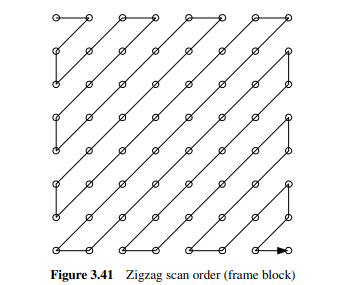

- **In the zigzag, the coefficients are reordered in a specific pattern that follows a zigzag path through the two-dimensional block of coefficients. This reordering process is used to group together coefficients with similar frequencies, which can help to improve the efficiency of the compression process.**

clear
clc

**The quantization tables **`qtable1`** and **`qtable2`** are used to specify the scale factors that are applied to the transformed coefficients during the quantization process. **

%define the quantization tables for the jpeg compression
%Q1 table
qtable1=[1 1 1 1 1 2 2 4;1 1 1 1 1 2 2 4;1 1 1 1 2 2 2 4,...
;1 1 1 1 2 2 4 8;1 1 2 2 2 2 4 8;2 2 2 2 2 4 8 8;...
2 2 2 4 4 8 8 16;4 4 4 4 8 8 16 16];
%Q2 table
qtable2=[1 2 4 8 16 32 64 128;2 4 4 8 16 32 64 128;...
4 4 8 16 32 64 128 128;8 8 16 32 64 128 128 256;...
16 16 32 64 128 128 256 256;32 32 64 128 128 256 256 256;...
64 64 128 128 256 256 256 256;128 128 128 256 256 256 256 256];

**Reading video files and returns a video object that can be used to access the frames of the video**

%reading the video
vid = VideoReader('xylophone.mp4');

**Retrieveing the first frame of the video using the **`readFrame`** function and converts it to grayscale using the **`rgb2gray`** function.**


%retrieving the inference frame
inf_frame = readFrame(vid);
inf_frame = double(rgb2gray(inf_frame));

#### **JPEG encoding and decoding on the first frame of the video. **

#### **The **`jpegenco`** function ****is a custom function that performs JPEG encoding on an image array. It takes the image array and a quantization table as input and returns the encoded image data, a dictionary of Huffman codes for the image data, and a list of indices for the encoded image data.**

####  **The **`jpegdeco`** function**** is a custom function that performs JPEG decoding on the encoded image data. It takes the encoded image data, the dictionary of Huffman codes, the list of indices, and the quantization table as input and returns the decoded image array. **

#### **The function **`estimation`** takes two inputs:**

-  `inference`** and **`current`**. **`inference`** is a frame from the video that has been previously encoded and decoded using JPEG, and **`current`** is the current frame from the video being processed. The function returns two outputs: **`motion_vector`** and **`difference_frame`**.**

- `motion_vector`** is a matrix that contains the motion vectors for each block in the current frame. A motion vector represents the displacement of a block in the current frame from its best match in the reference frame (in this case, the **`inference`** frame).**

- `difference_frame`** is a matrix that contains the difference between the current frame and the reference frame, block by block. This difference is calculated by subtracting the best match for each block in the reference frame from the corresponding block in the current frame.**

#### **Reconstructed frame is created by adding a decoded difference frame to an inference frame.**

- **The code loops through the rows and columns of the decoded difference frame in 8x8 blocks, using the reshaped motion vector to access corresponding blocks in the inference frame. The difference and inference blocks are added together to create a reconstructed block, which is then concatenated with other reconstructed blocks to form the whole reconstructed frame.**

- **The reconstructed frame is then cast to a uint8 data type and written to a video**

%jpeg encoding and decoding the inference frame
[encoded,dict,allindices] = jpegenco(inf_frame,qtable2);
compressed_inf = jpegdeco(encoded,dict,allindices,qtable2,size(inf_frame,1),size(inf_frame,2));
compressed_inf = double(compressed_inf);
s = VideoWriter('reconstructed1_video_High_compression.avi');
open(s);
sum_decoded_motion_vector=[];
 sum_encoded_difference_frame=[];
writeVideo(s,uint8(inf_frame));

%looping over the video frames
tic
while hasFrame(vid)
    
        curr_frame = readFrame(vid);
        curr_frame = double(rgb2gray(curr_frame));
   
 %estimation and compensation
 [motion_vector,difference_frame] = estimation(compressed_inf,curr_frame);

 
 %%%%%%%%%%%%%%% encoding step:%%%%%%%%%%%%%%%%%%%%%%%
 %jpeg encoding the difference frame
 [encoded_difference_frame,dict_1,allindices] = jpegenco(difference_frame,qtable2);
 sum_encoded_difference_frame = [sum_encoded_difference_frame encoded_difference_frame];
 
 %Huffman encoding the motion vector 
[symbols,prob] = probdist(motion_vector);
motion_dict = huffmandict(symbols,prob);

%%%%%%%%%%%%%%% Decoding step:%%%%%%%%%%%%%%%%%%%%%%%
%jpeg decoding the difference frame
 decoded_difference_frame = jpegdeco(encoded_difference_frame,dict_1,allindices,qtable2,size(difference_frame,1),size(difference_frame,2));
  
encoded_motion_vector=huffmanenco(motion_vector,motion_dict);
sum_decoded_motion_vector=[sum_decoded_motion_vector encoded_motion_vector]; 
%Huffman decoding the motion vector
decoded_motion_vector = huffmandeco(encoded_motion_vector,motion_dict);
%reshaping the decoded motion vector into a 2D array where each row represents the top left indicies of the 8*8 block 
reshaped_motion_vector = [];
c=1;

for i=1:2:length(decoded_motion_vector)
     reshaped_motion_vector(c,1) = decoded_motion_vector(i);  
     reshaped_motion_vector(c,2) = decoded_motion_vector(i+1);
     c=c+1;
end
%reconstruction step where the inference and the difference frame are
%added together
rc = size(decoded_difference_frame,1);
cc = size(decoded_difference_frame,2);
reconstructed_frame = zeros(rc,cc);

%reconstructing the inference frame
k=1;
for i=1:8:rc-8
    for j=1:8:cc-8
        %indicies for accessing the motion vector
        m = reshaped_motion_vector(k,1);
        n = reshaped_motion_vector(k,2);
      decoded_difference_block = double(decoded_difference_frame(i:i+7,j:j+7));
      infer_block = double(compressed_inf(m:m+7,n:n+7));
      reconstructed_block = decoded_difference_block + infer_block;
      %concatenating the blocks to contsruct the whole frame
      reconstructed_frame(i:i+7,j:j+7) = reconstructed_block;
      k=k+1;
    end
end
reconstructed_frame = uint8(reconstructed_frame);
writeVideo(s,reconstructed_frame);
end
toc

Elapsed time is 103.472088 seconds.


**The compression ratio of a video after applying a motion estimation and compensation (MEC) algorithm.**

num_b_before_comp = 8 * vid.NumFrames * vid.Height * vid.Width;
num_b_after_compr = length(sum_encoded_difference_frame) + length(sum_decoded_motion_vector);
CompressionRatio = num_b_before_comp / num_b_after_compr;
fprintf("The Compression Ratio is %f \n  ", CompressionRatio);

The Compression Ratio is 7.253229 
  

close(s);

## Questions answering:

compression ratio after using the Quantization table 1 (low compression) = 3.925181263545987

compression ratio after using the Quantization table 2 (high compression) =  7.2532

## **Evaluation test:**